# Disaster Preparedness and Response Capacity Optimization of Humanitarian Supply Chain Network Design For Developing Countries: 

## Graph:

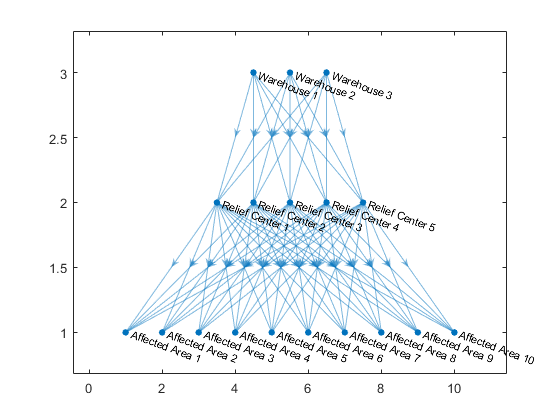

s={'Warehouse 1' 'Warehouse 1' 'Warehouse 1' 'Warehouse 1' 'Warehouse 1' 'Warehouse 2' 'Warehouse 2' 'Warehouse 2' 'Warehouse 2' 'Warehouse 2' 'Warehouse 3' 'Warehouse 3' 'Warehouse 3' 'Warehouse 3' 'Warehouse 3'...
    'Relief Center 1' 'Relief Center 1' 'Relief Center 1' 'Relief Center 1' 'Relief Center 1' 'Relief Center 1' 'Relief Center 1' 'Relief Center 1' 'Relief Center 1' 'Relief Center 1'...
    'Relief Center 2' 'Relief Center 2' 'Relief Center 2' 'Relief Center 2' 'Relief Center 2' 'Relief Center 2' 'Relief Center 2' 'Relief Center 2' 'Relief Center 2' 'Relief Center 2'...
    'Relief Center 3' 'Relief Center 3' 'Relief Center 3' 'Relief Center 3' 'Relief Center 3' 'Relief Center 3' 'Relief Center 3' 'Relief Center 3' 'Relief Center 3' 'Relief Center 3'...
    'Relief Center 4' 'Relief Center 4' 'Relief Center 4' 'Relief Center 4' 'Relief Center 4' 'Relief Center 4' 'Relief Center 4' 'Relief Center 4' 'Relief Center 4' 'Relief Center 4'...
    'Relief Center 5' 'Relief Center 5' 'Relief Center 5' 'Relief Center 5' 'Relief Center 5' 'Relief Center 5' 'Relief Center 5' 'Relief Center 5' 'Relief Center 5' 'Relief Center 5'};
t={'Relief Center 1' 'Relief Center 2' 'Relief Center 3' 'Relief Center 4' 'Relief Center 5' 'Relief Center 1' 'Relief Center 2' 'Relief Center 3' 'Relief Center 4' 'Relief Center 5' 'Relief Center 1' 'Relief Center 2' 'Relief Center 3' 'Relief Center 4' 'Relief Center 5'...
    'Affected Area 1' 'Affected Area 2' 'Affected Area 3' 'Affected Area 4' 'Affected Area 5' 'Affected Area 6' 'Affected Area 7' 'Affected Area 8' 'Affected Area 9' 'Affected Area 10'...
    'Affected Area 1' 'Affected Area 2' 'Affected Area 3' 'Affected Area 4' 'Affected Area 5' 'Affected Area 6' 'Affected Area 7' 'Affected Area 8' 'Affected Area 9' 'Affected Area 10'...
    'Affected Area 1' 'Affected Area 2' 'Affected Area 3' 'Affected Area 4' 'Affected Area 5' 'Affected Area 6' 'Affected Area 7' 'Affected Area 8' 'Affected Area 9' 'Affected Area 10'...
    'Affected Area 1' 'Affected Area 2' 'Affected Area 3' 'Affected Area 4' 'Affected Area 5' 'Affected Area 6' 'Affected Area 7' 'Affected Area 8' 'Affected Area 9' 'Affected Area 10'...
    'Affected Area 1' 'Affected Area 2' 'Affected Area 3' 'Affected Area 4' 'Affected Area 5' 'Affected Area 6' 'Affected Area 7' 'Affected Area 8' 'Affected Area 9' 'Affected Area 10'};
G=digraph(s,t); 
plot(G)    

prob=optimproblem('ObjectiveSense','maximize')

prob =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'maximize'
         Variables: [0×0 struct] containing 0 OptimizationVariables
         Objective: [0×0 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  No problem defined.


## Sets:

node_warehouse=3;  % Condidate nodes for warehouses 
relief_centers=5;  % Condidate nodes for relief centers
areas=10; % Affected areas
items=7;  % Relief aid items (units)
mac_perios=2;  % Macrotime period
mic_perios=4;  % Microtime period

## Variables:

X=optimvar('X',node_warehouse,relief_centers,1,'Type','integer','LowerBound',0,'UpperBound',10000000); %Amount of relief aid procured at relief center from warehouse at microtime period (units)
Z=optimvar('Z',areas,relief_centers,'Type','integer','LowerBound',0,'UpperBound',10000000); %Fraction of the victims needs associated with affected area that is assigned to relief center at microtime period
Y1=optimvar('Y1',node_warehouse,1,'Type','integer','LowerBound',0,'UpperBound',1); % =1 if warehouse is installed at macrotime period and =0 otherwise
Y2=optimvar('Y2',1,relief_centers,'Type','integer','LowerBound',0,'UpperBound',1); % =1 if relief center is installed at macrotime period and =0 otherwise
Iw=optimvar('Iw',node_warehouse,1,mac_perios,'Type','integer','LowerBound',0,'UpperBound',10000000); %Inventory of relief aid at warehouse at macrotime period  (units)
Pw=optimvar('Pw',node_warehouse,1,mac_perios,'Type','integer','LowerBound',0,'UpperBound',10000000); %amount of relief aid prepositioned at warehouse at macrotime period
Ir=optimvar('Ir',1,relief_centers,mac_perios,'Type','integer','LowerBound',0,'UpperBound',10000000);%Inventory of relief aid at relief center at macrotime period (units)
Qw=optimvar('Qw',node_warehouse,1,mac_perios,'Type','integer','LowerBound',0,'UpperBound',10000000); %Capacity of warehouse 
UQw=optimvar('UQw',node_warehouse,1,mac_perios,'Type','integer','LowerBound',0,'UpperBound',10000000); %Uninstalled Capacity of warehouse 
IQw=optimvar('IQw',node_warehouse,1,mac_perios,'Type','integer','LowerBound',0,'UpperBound',10000000); %Installed Capacity of warehouse 
Uw=optimvar('Uw',node_warehouse,1,mac_perios,'Type','integer','LowerBound',0,'UpperBound',10000000); %Expended Capacity of warehouse 
Qr=optimvar('Qr',1,relief_centers,mac_perios,'Type','integer','LowerBound',0,'UpperBound',10000000); %Capacity of relief center
UQr=optimvar('UQr',1,relief_centers,mac_perios,'Type','integer','LowerBound',0,'UpperBound',10000000); %Uninstalled Capacity of relief center
IQr=optimvar('IQr',1,relief_centers,mac_perios,'Type','integer','LowerBound',0,'UpperBound',10000000); %Installed Capacity of relief center
Ur=optimvar('Ur',1,relief_centers,mac_perios,'Type','integer','LowerBound',0,'UpperBound',10000000); %Expended Capacity of relief center

## Parameters:

Cx=randi([10 1000],node_warehouse,relief_centers); %cost of opening warehouse
Cz=randi([10 1000],areas,relief_centers); %cost of opening relief center
f1=randi([10000 100000],node_warehouse,1); %Fixed cost of opening warehouse
f2=randi([10000 100000],1,relief_centers); %Fixed cost of opening relief center
Vr=[0.26052 0.08935 0.2569 0.0469 0.01022 0.6366 0.0252 0.1971 0.03388 0.01607]; %Relative number of victims at affected area at microtime period
SoVIa=1; %Expected value of Social Vulnerability Index associated with affected area a 

## Objective function:

prob.Objective=sum(sum(Cx.*X))+sum(sum(Cz.*Z))+sum(sum(f1.*Y1))+sum(sum(SoVIa.*Vr*Z));

## Constraints:

% Procurement Capacity
procure_con=Uw==Iw+IQw;
procure_con1=Ur==Ir+IQr;
% Changing Capacity
Intital_Cap=Qw(:,:,1)==randi([100000  10000000],node_warehouse,1)

Intital_Cap =   3×1 OptimizationConstraint array with properties:

    IndexNames: {{}  {}}

  See constraint formulation with showconstr.


chang_cap=Qw(:,:,2:end)==Qw(:,:,1:end-1)-UQw(:,:,2:end)+IQw(:,:,2:end);
Intital_Cap1=Qr(:,:,1)==randi([100000  10000000],1,relief_centers)

Intital_Cap1 =   1×5 OptimizationConstraint array with properties:

    IndexNames: {{}  {}}

  See constraint formulation with showconstr.


chang_cap1=Qr(:,:,2:end)==Qr(:,:,1:end-1)-UQr(:,:,2:end)+IQr(:,:,2:end);
% Capacity Constraints 
Supply_con1=sum(X(:,:,1),2)<=randi([100000  10000000],node_warehouse,1);
Supply_con2=sum((sum(X(:,:,2:end),2)),3)<=Qw(:,:,2:end)

Supply_con2 =   3×1 OptimizationConstraint array with properties:

    IndexNames: {{}  {}}

  See constraint formulation with showconstr.


Cap_r=sum(sum(X(:,:,1),2))<=randi([100000  10000000],1,relief_centers);
Cap_r1=sum(sum(sum(X(:,:,2:end),2)),3)<=Qr(:,:,2:end)

Cap_r1 =   1×5 OptimizationConstraint array with properties:

    IndexNames: {{}  {}}

  See constraint formulation with showconstr.


% Transhipment constraint 
Tranship_con=sum(X,1)>=sum(Z,1);
% Demand Constraint 
Demand=randi([1000 10000],areas,1);
demand_con=sum(Z,2)==Demand;
% Inventory Constraint 
IInvCon=Iw==randi([1000  1000000],node_warehouse,1,mac_perios) % initial inventory level of each Warehouse

IInvCon =   3×1×2 OptimizationConstraint array with properties:

    IndexNames: {{}  {}  {}}

  See constraint formulation with showconstr.


g=sum(X,1)-sum(Z,1); 
Inv_con=Iw>=sum(sum(sum(g,1)))

Inv_con =   3×1×2 OptimizationConstraint array with properties:

    IndexNames: {{}  {}  {}}

  See constraint formulation with showconstr.


Con_preposition=Pw>=10000;
SS=Pw; 
SS_con=Iw>=Pw;
Q=sum(X,1);
Finv_con=Iw(2:mac_perios)==Ir(1:mac_perios)+Q(2:mac_perios);


## Standard Constraints:

prob.Constraints.SS_con=SS_con;
prob.Constraints.Finv_con=Finv_con;
prob.Constraints.IInvCon=IInvCon;
prob.Constraints.demand_con=demand_con;
prob.Constraints.Supply_con1=Supply_con1;
prob.Constraints.Supply_con2=Supply_con2;
prob.Constraints.Tranship_con=Tranship_con;
prob.Constraints.Con_preposition=Con_preposition

prob =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'maximize'
         Variables: [1×1 struct] containing 7 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 8 OptimizationConstraints

  See problem formulation with showproblem.


prob.Constraints.Intital_Cap1=Intital_Cap1;
prob.Constraints.chang_cap1=chang_cap1;
prob.Constraints.procure_con1=procure_con1;
prob.Constraints.Cap_r=Cap_r

prob =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'maximize'
         Variables: [1×1 struct] containing 11 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 12 OptimizationConstraints

  See problem formulation with showproblem.


prob.Constraints.Cap_r1=Cap_r1

prob =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'maximize'
         Variables: [1×1 struct] containing 11 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 13 OptimizationConstraints

  See problem formulation with showproblem.


[x, fval]=solve(prob)

LP:                Optimal objective value is -5.113414e+09.                                        


Optimal solution found.

Intlinprog stopped at the root node because the objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon variables are integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).



x = struct with fields:
    IQr: [1×5×2 double]
     Ir: [1×5×2 double]
     Iw: [3×1×2 double]
     Pw: [3×1×2 double]
     Qr: [1×5×2 double]
     Qw: [3×1×2 double]
    UQr: [1×5×2 double]
     Ur: [1×5×2 double]
      X: [3×5 double]
     Y1: [3×1 double]
      Z: [10×5 double]


fval = 5.1134e+09